# Sed Stats example

% Jacob Stasiewicz
clear; clc;

## Loading Data

sample_percent = readtable("Wilmington_Percentages_1.csv")

sample_percent = 20×20 table
         sample          sample_number    tinWeight_g_    tin_sampleWeight_g_    sampleWeight_g_    x2mm    x1mm    x500um    x250um    x125um    x63um    x_63um    sedimentsTotal    x2mm___    x1mm___    x500um___    x250um___    x125um___    x63um___    x_63um___
    _________________    _____________    ____________    ___________________    _______________    ____    ____    ______    ______    ______    _____    ______

model_out = readtable("wb_17FEB2022.csv")

model_out = 20×16 table
    Filename    Date_Time_UTC_    Latitude_DD_    Longitude_DD_    Altitude_m_    D_2_mm_    D_5_mm_    D_10_mm_    D_16_mm_    D_25_mm_    D_50_mm_    D_75_mm_    D_84_mm_    D_90_mm_    D_95_mm_    D_98_mm_
    ________    ______________    ____________    _____________    ___________    _______    _______    ________    ________    ________    ________    ________    ________    ________    ________    ________

        1    

## Parsing Data

table_size = size(sample_percent)

table_size =     20    20


percents = sample_percent{1:table_size(1),14:20};
percents(percents == 0) = 0.00001;

ts = size(model_out);
estimated = model_out{1:ts, 6:16};

## Running SedStats

x = [2,1,.5,.250,.125,.063,0];
phis = -log2(x);

actual = [];
for i = 1:table_size
    [d_out] = SedStats(phis,'percent',percents(i,:));
    actual = [actual; d_out];
end

d_vals_phi =     3.2835    2.9752    2.9197    2.8532    2.7534    2.4761    2.1988    2.0990    2.0325    1.6947    1.2522


d_vals_phi =     3.2582    2.9754    2.9218    2.8576    2.7613    2.4936    2.2260    2.1296    2.0654    2.0119    1.5116


d_vals_phi =     3.3227    2.9768    2.9201    2.8522    2.7502    2.4670    2.1838    2.0819    2.0139    1.5575    1.2054


d_vals_phi =     2.9980    2.9613    2.9001    2.8267    2.7166    2.4107    2.1047    1.9731    1.6064    1.3007    1.1174


d_vals_phi =     2.9506    2.8696    2.7347    2.5727    2.3298    1.6780    1.0481    0.6423    0.3396    0.0873   -0.4058


d_vals_phi =     2.9940    2.9630    2.9113    2.8493    2.7564    2.4980    2.2397    2.1467    2.0847    2.0331    2.0021


d_vals_phi =     2.9928    2.9578    2.8994    2.8294    2.7245    2.4328    2.1412    2.0362    1.7720    1.3789    1.1431


d_vals_phi =     3.2096    2.9743    2.9224    2.8601    2.7665    2.5068    2.2471    2.1536    2.0912    2.0393    2.0081


d_vals_phi =     3.0243    2.9687    2.9156    2.8520    2.7564    2.4911    2.2258    2.1303    2.0666    2.0136    1.5339


d_vals_phi =     2.9779    2.9286    2.8463    2.7476    2.5995    2.1881    1.6391    1.3997    1.2402    1.1072    1.0274


d_vals_phi =     2.9958    2.9382    2.8422    2.7270    2.5542    2.0743    1.4298    1.1870    1.0251    0.4058   -0.1158


d_vals_phi =     2.9879    2.9359    2.8494    2.7455    2.5896    2.1567    1.4932    1.2072    1.0165    0.4667    0.1095


d_vals_phi =     2.9208    2.6902    2.3059    1.9676    1.8233    1.4226    1.0218    0.6284    0.3366    0.0934   -0.3699


d_vals_phi =     2.9933    2.9583    2.8999    2.8298    2.7247    2.4327    2.1407    2.0356    1.7684    1.3760    1.1405


d_vals_phi =     3.0696    2.9703    2.9182    2.8557    2.7620    2.5015    2.2411    2.1473    2.0848    2.0327    2.0015


d_vals_phi =     2.9982    2.9660    2.9123    2.8479    2.7512    2.4828    2.2144    2.1178    2.0534    1.9939    1.3791


d_vals_phi =     2.9963    2.9627    2.9067    2.8394    2.7386    2.4584    2.1783    2.0774    2.0102    1.5486    1.2174


d_vals_phi =     2.9933    2.9504    2.8790    2.7933    2.6648    2.3078    1.8768    1.5555    1.3413    1.1628    1.0557


d_vals_phi =     3.4814    2.9862    2.9244    2.8502    2.7390    2.4301    2.1211    2.0099    1.5229    1.0642    0.4471


d_vals_phi =     3.2824    2.9504    2.8377    2.7024    2.4995    1.8196    0.5431    0.2032   -0.0589   -0.5337   -0.8186



%Finding MAPE
MAPE = (abs(estimated-actual)./actual)*100;

MAPE =    12.9503    6.1562   12.7472   19.9490   21.3710   20.7370   19.3692   24.6710   29.2792   15.2397    3.0501
    7.1591    4.5995   11.3991   18.1452   20.6825   19.9602   19.7652   26.0315   30.1700   41.9645   14.0522
   19.0640    9.4244   15.8087   22.0329   24.4722   23.2982   22.2238   26.5858   32.0693    8.9078    3.1476
    7.3259    6.7014   12.7218   18.4801   20.2893   16.9787   13.9825   16.6057    2.5658   10.3272   10.3999
   17.5073   33.0203   39.7787   34.4560   26.1888    5.5951    7.9812   20.0873   27.3679   29.6711   43.2358
    9.9748    6.0458   12.8479   19.6321   21.6236   23.7166   23.2716   30.1894   35.7424   47.3384   63.8345
    7.6641    4.1075   12.6666   18.7037   19.6245   18.7872   15.5723   20.5851    9.9726    6.3729    9.0090
    5.4574    6.8818   12.1989   19.0708   23.8467   22.1974   22.9514   29.4728   33.7980   46.3296   62.9125
    5.6212    8.0301   12.4291   20.5706   24.3343   23.1265   23.0261   30.0309   33.6327   46.1698   19

## Ploting Error

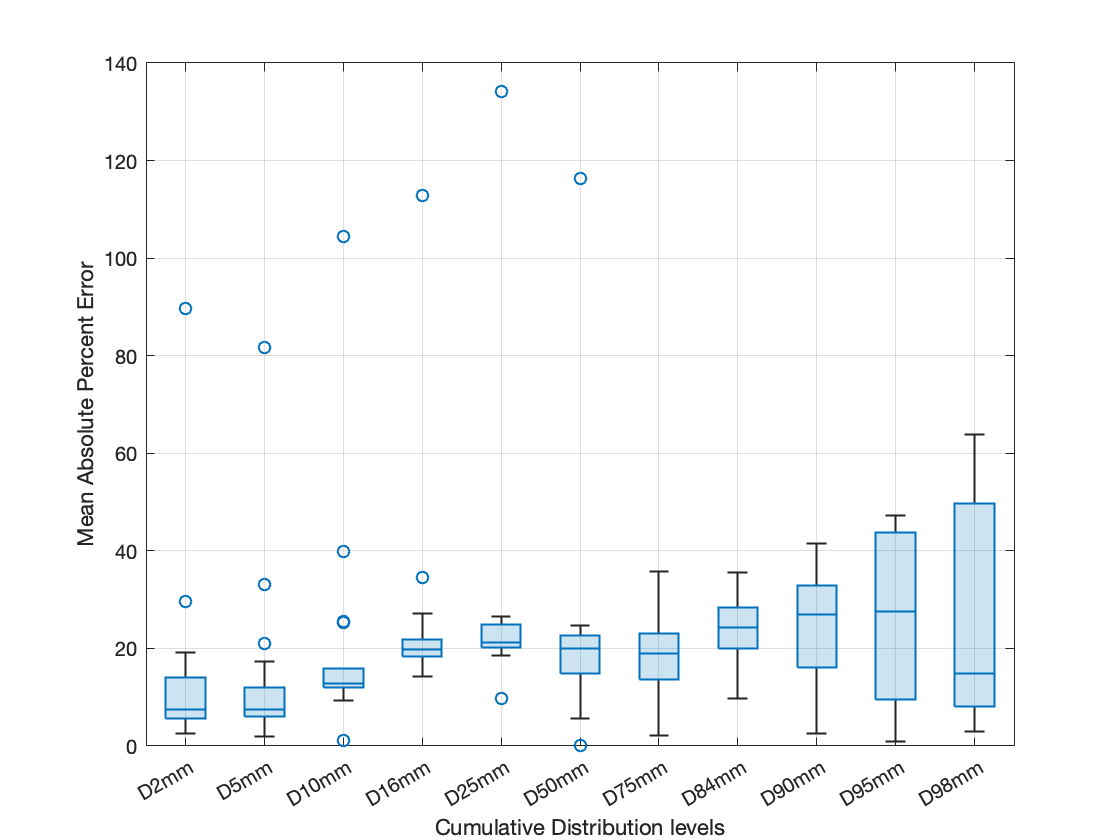

figure;
boxchart(MAPE), box on, grid on
xticklabels({"D2mm", "D5mm", "D10mm", "D16mm", "D25mm", "D50mm", "D75mm", "D84mm", "D90mm", "D95mm", "D98mm"})
xlabel("Cumulative Distribution levels")
ylabel("Mean Absolute Percent Error")